clear all, close all,clc
% Authors: A. Alassaf, Lingling Fan
%===================================
% n input signals
% 08/31/2019

% 09/9/2019

% 09/12 /2019 : 
% found b could mislead solution 
% the Admd cannot match Asys, but the eigenvalues.

% 09/13 /2019 : 
% FFT

## Data Setting:-

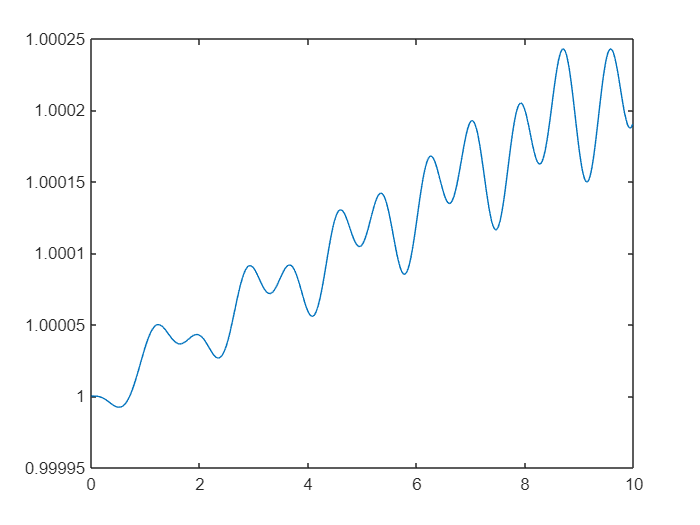

load('torque_stepchange_data.mat', 'bus_v')
load('torque_stepchange_data.mat', 'dmac_spd')     % speed deviation data
load('torque_stepchange_data.mat', 'mac_spd')     % speed data 
%  load('torque_stepchange_data.mat', 'dmac_ang')     % thata data
%  load('svm_mgen_data.mat', 'mac_state')           %state varables
                                                  % 1=thata & 2=speed 
                             
% ang_idx = find(mac_state(:,2)==1);
% spd_idx = find(mac_state(:,2)==2);

dt=0.01;
ts=0.01; % start time of data
tf=9.99; % final time of data
tot=tf-ts; %total time
 
ss=1; % Number of signals
y=[];
 
% y(ang_idx,:)=dmac_ang(1:4,ts/dt:tf/dt);
% y(spd_idx,:)=dmac_spd(1:4,ts/dt:tf/dt);

 %bus(10,1)  is bus 20
 %bus(14,1)  is bus 120
%  
y(1,:)=1*mac_spd(3,ts/dt:tf/dt);
figure;
plot(0:dt:length(y(1,:))*dt-dt, y(1,:));

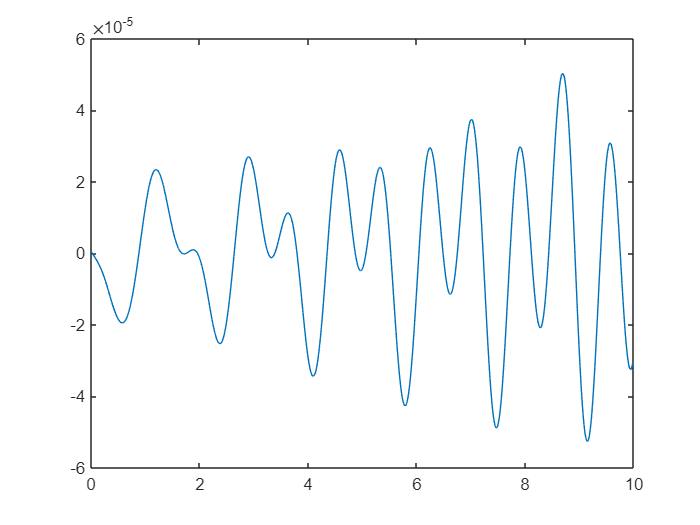

y=detrend(y,'linear');
figure;
plot(0:dt:length(y)*dt-dt, y);

## Build The measurement matrix

rows=500% higher could be better

rows = 500

m=length(y)-rows;
d1=0; %dummy variable for counting
   for counter=1:rows
      f(counter+d1:counter+d1+ss-1,1:m+1)= y(:,counter:m+counter);  
      d1=d1+(ss-1);
   end

## DMD operations

X=f;
X1=X(:,1:end-1);
X2=X(:,2:end);
size(X1)

ans =    500   499


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The system order
r=10; %ss%rank(X1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[U,S,V]=svd(X1,'econ');
Ur=U(:,1:r); %To get the most effective if U
Vr=V(:,1:r); %To get the most effective of V
Sr=S(1:r,1:r); %To get the active eigenvalues
Atilda=Ur'*X2*Vr/Sr;
[W,D]=eig(Atilda); % to get the eigenvectors and eigenvalues
    Phi=X2*Vr/Sr*W; %exact modes
%          Phi=Ur*W;  %Projected modes
lambda=(diag(D)); % the eigenvalues are the diag of D
omega=log(lambda)/dt; %to get the value of omega form (exp(omega*t))
freq=imag(omega)/(2*pi);% In Hz
Eig=real(omega)+1i*freq;
P_freq=freq( freq>=0 ); % positive freq
x1=X1(:,1); % the intial condtion (x0)       <---  test it 
b=Phi\(x1); %from the equation Phi*b=x1
  

#### Reconstruct the signal based on the eigenvlaues. 

 t2=[0:dt:tf];
  time_dynamics_new=zeros(r,length(t2));
for iter= 1:length(t2) 
 time_dynamics_new(:,iter)=(b.*exp(omega*t2(iter)));  
end
  X_dmd2=Phi*time_dynamics_new;
  size(X_dmd2)

ans =          500        1000


## plots

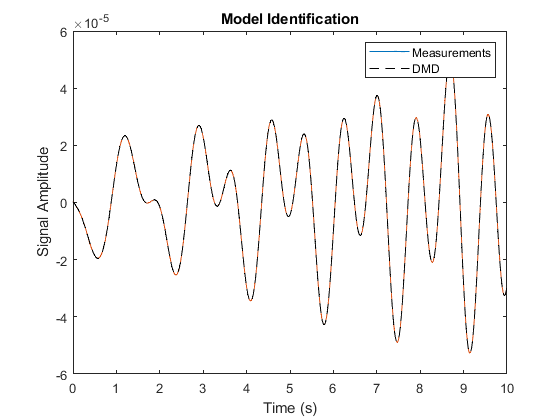

figure(1)
for k=1:ss
%plot(t2(1:length(y)),real(y(k,:)),'Linewidth',[1]) ,
plot(t2(1:length(y)),(y(k,:)),'Linewidth',[1]) ,
   hold on, 
end

for k=1:ss
plot(t2,real(X_dmd2(k,:)),'k--','Linewidth',[1]) 
 hold on, 
end
  legend('Measurements','DMD')
title('Model Identification')
xlabel('Time (s)'), ylabel('Signal Amplitude')

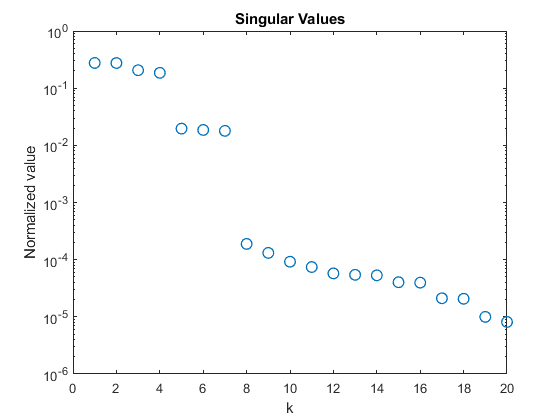

%  legend('Measurement','DMD')
%   legend('Bus3','Bus13','DMD1','DMD2')

figure;
semilogy(diag(S)/(sum(diag(S))),'o','Linewidth',[1],'MarkerSize',8)
 xlim([0,20]); %axis([0 50 0 0.35])
title('Singular Values')
xlabel('k'), ylabel('Normalized value')

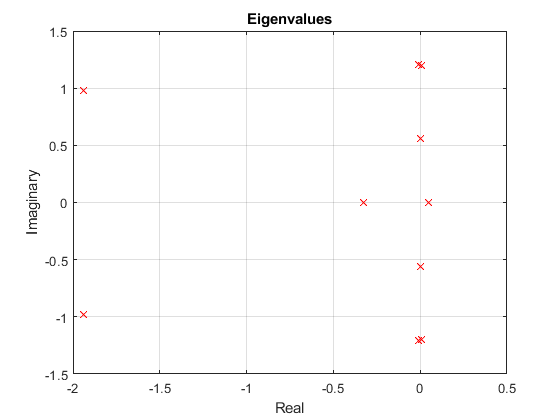


% figure(4)
% 
% for k=1:r
% subplot(r,1,k),
% plot(U(:,k)),  
% end

%
figure(5)
  plot(Eig,'rX')
title('Eigenvalues')
xlabel('Real'), ylabel('Imaginary')
 grid

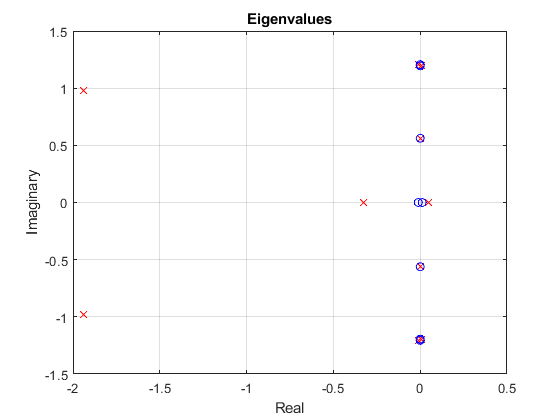

load('svm_mgen_data.mat', 'a_mat')
a_mat;
Eig_mat=eig(a_mat);
Eig1 = real(Eig_mat)+1i*imag(Eig_mat)/2/pi;
hold on;
 plot(Eig1,'bO')

## DMDvsFFT

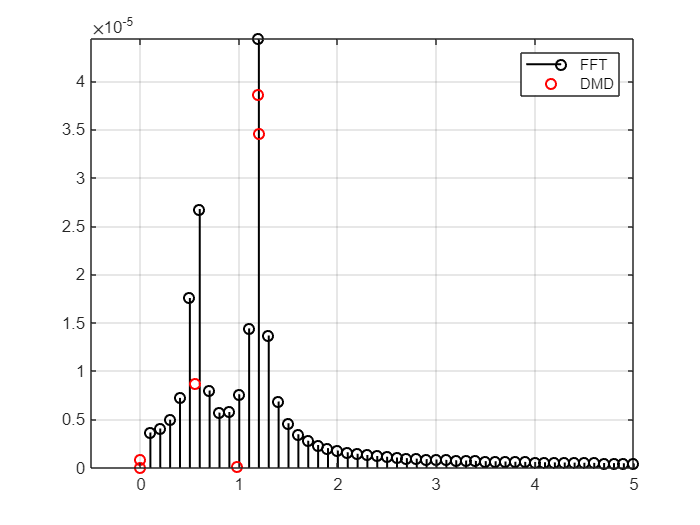

xhat = fft(y);
N = length(t2);  % number of samples
xpower = abs(xhat(1:N/2+1))*2/N;
Fs = 1/dt;      % sampling frequency
freqs = Fs*(0:(N/2))/N;
% maxFreq = N/8;

dd=1;
b = Phi\X(:,dd);  
%  need to scale power by 2/sqrt(s)

DMDfreqs = log(diag(D))/dt/2/pi;  
%DMDpower = (abs(b)*2/sqrt(rows));%./(abs(lambda).^(dd)); 
DMDpower = (abs(b)/sqrt(rows));%./(abs(lambda).^(dd)); 


figure;
stem(freqs,xpower*2,'k','LineWidth',1.2)
% plot(freqs(1:maxFreq),xpower(1:maxFreq),'k','LineWidth',1.2)
grid on, hold on
scatter(abs(imag(DMDfreqs)),DMDpower,'r','LineWidth',1.2)
   axis([-0.5 5 0 inf])
legend('FFT','DMD')